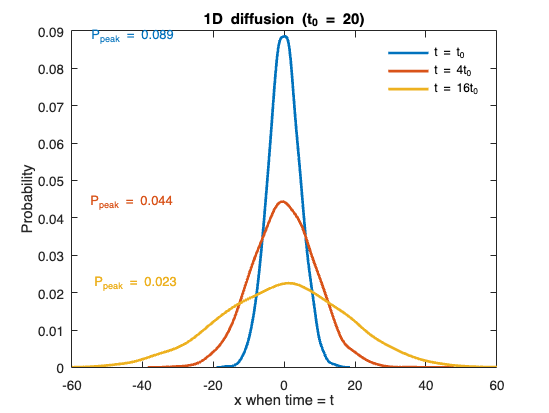

%plotting Smoothed PDF Curves and Calculating MSDs for 1D Diffusion

figure;
hold on;
box on;

%define color scheme
colors = lines;

%estimate probability density functions from simulation data
[pdf_t_1, x_1] = ksdensity(x_ts_1);
[pdf_t_4, x_4] = ksdensity(x_ts_4);
[pdf_t_16, x_16] = ksdensity(x_ts_16);

%plot smoothed curves for each timepoint
plot(x_1, pdf_t_1, 'LineWidth', 2, 'Color', colors(1, :));
plot(x_4, pdf_t_4, 'LineWidth', 2, 'Color', colors(2, :));
plot(x_16, pdf_t_16, 'LineWidth', 2, 'Color', colors(3, :));

%legend and labels
legend("t = t_0", "t = 4t_0", "t = 16t_0", "Box", "off");
xlabel('x when time = t');
ylabel('Probability');
title('1D diffusion (t_0 = 20)');

%fix x-axis range
xlim([-60, 60]);

%find peaks of each pdf (highest probability values)
[pks_t_1, locs_t_1] = findpeaks(pdf_t_1, 'SortStr', 'descend');
[pks_t_4, locs_t_4] = findpeaks(pdf_t_4, 'SortStr', 'descend');
[pks_t_16, locs_t_16] = findpeaks(pdf_t_16, 'SortStr', 'descend');

%annotate peak probability on plot for each curve
if length(pks_t_1) >= 1
    text(x_1(locs_t_1(1)) - 55, pks_t_1(1), ["P_{peak} = " + num2str(pks_t_1(1), 2)], 'Color', colors(1, :));
end
if length(pks_t_4) >= 1
    text(x_4(locs_t_4(1)) - 55, pks_t_4(1), ["P_{peak} = " + num2str(pks_t_4(1), 2)], 'Color', colors(2, :));
end
if length(pks_t_16) >= 1
    text(x_16(locs_t_16(1)) - 55, pks_t_16(1), ["P_{peak} = " + num2str(pks_t_16(1), 2)], 'Color', colors(3, :));
end

%calculate mean squared displacement at each timepoint
msd_t_1 = mean(x_ts_1.^2);
msd_t_4 = mean(x_ts_4.^2);
msd_t_16 = mean(x_ts_16.^2);

%print MSD values to console
fprintf('MSD(t=t0) = %.4f\n', msd_t_1);

MSD(t=t0) = 19.6083


fprintf('MSD(t=4t0) = %.4f\n', msd_t_4);

MSD(t=4t0) = 81.1007


fprintf('MSD(t=16t0) = %.4f\n', msd_t_16);

MSD(t=16t0) = 313.3036
